
=== Vibration Analysis System ===
omega_n = 70.7107 rad/s
f_n     = 11.2540 Hz
zeta    = 0.7071 [-]
Type: underkritisk dæmpet (oscillerende)

--- Peak metrics (magnitude) ---
x_peak = 0.001 m at t=0 s (signed: 0.001)
v_peak = 0.0322394 m/s at t=0.0157696 s (signed: -0.0322394)
a_peak = 5 m/s^2 at t=0 s (signed: -5)


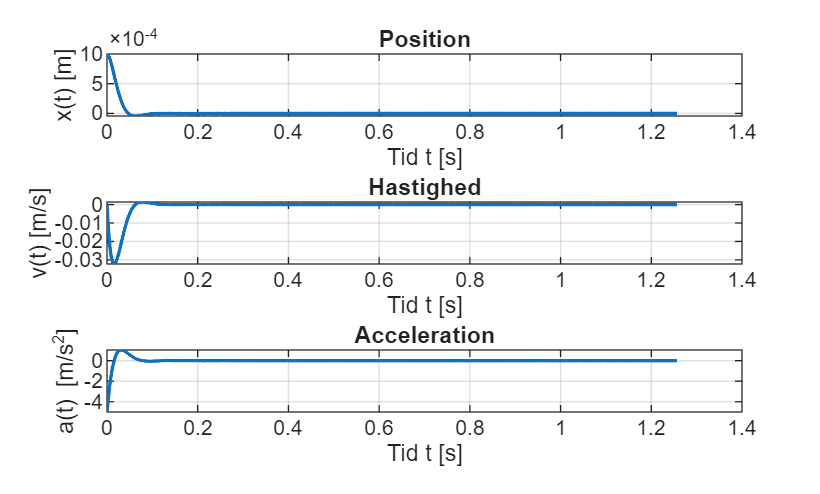

function out = vibration_analysis_system(m, k, c, x0, v0, F_func, t_end, opts)
% VIBRATION_ANALYSIS_SYSTEM.--
% 2. ordens system: m*xdd + c*xd + k*x = F(t)
%
% INPUT
%   m, k, c : systemparametre
%   x0, v0  : initialbetingelser
%   F_func  : funktionshåndtag, skal kunne tage vektor T -> F(T)
%             hvis tom: F(t)=0
%   t_end   : (valgfri) simuleringstid [s], hvis tom vælges automatisk
%   opts    : (valgfri) struktur med options:
%             opts.solver   = "ode45" (default) eller "ode15s"
%             opts.RelTol   = 1e-8 (default)
%             opts.AbsTol   = 1e-10 (default)
%             opts.doPlot   = true/false (default true)
%             opts.verbose  = true/false (default true)
%
% OUTPUT (struktur) out med felter:
% out.params, out.info, out.T, out.X, out.V, out.A, out.F, out.metrics

%% --- 0) Defaults / input handling ---------------------------------------
if nargin < 6 || isempty(F_func)
    F_func = @(t) zeros(size(t));
end

if nargin < 8 || isempty(opts)
    opts = struct();
end

if ~isfield(opts, "solver")  || isempty(opts.solver),  opts.solver  = "ode45"; end
if ~isfield(opts, "RelTol")  || isempty(opts.RelTol),  opts.RelTol  = 1e-8;    end
if ~isfield(opts, "AbsTol")  || isempty(opts.AbsTol),  opts.AbsTol  = 1e-10;   end
if ~isfield(opts, "doPlot")  || isempty(opts.doPlot),  opts.doPlot  = true;    end
if ~isfield(opts, "verbose") || isempty(opts.verbose), opts.verbose = true;    end

% Gem parametre
out = struct();
out.params = struct('m', m, 'k', k, 'c', c, 'x0', x0, 'v0', v0);

%% --- 1) Afledte størrelser ----------------------------------------------
omega_n = sqrt(k/m);            % rad/s
zeta    = c/(2*sqrt(m*k));      % -
f_n     = omega_n/(2*pi);       % Hz

out.info = struct('omega_n', omega_n, 'zeta', zeta, 'f_n', f_n);

if opts.verbose
    fprintf('\n=== Vibration Analysis System ===\n');
    fprintf('omega_n = %.4f rad/s\n', omega_n);
    fprintf('f_n     = %.4f Hz\n', f_n);
    fprintf('zeta    = %.4f [-]\n', zeta);

    if zeta < 1
        fprintf('Type: underkritisk dæmpet (oscillerende)\n');
    elseif abs(zeta-1) < 1e-3
        fprintf('Type: ~kritisk dæmpet\n');
    else
        fprintf('Type: overkritisk dæmpet (ikke-oscillerende)\n');
    end
end

%% --- 2) Automatisk simuleringstid ---------------------------------------
if nargin < 7 || isempty(t_end)
    if zeta < 1
        omega_d = omega_n*sqrt(1 - zeta^2);
        T_d     = 2*pi/omega_d;
        t_end   = 10*T_d;
    else
        % Tommelfingerregel for transients: ~ 10 / (zeta*omega_n)
        t_end = 10/(max(zeta,1e-6)*omega_n);
    end
end

tspan = [0 t_end];
out.info.t_end = t_end;

%% --- 3) 1. ordens system -------------------------------------------------
% y(1)=x, y(2)=v
y0 = [x0; v0];

eom = @(t,y) [y(2); (F_func(t) - c*y(2) - k*y(1))/m ];

%% --- 4) Numerisk løsning -------------------------------------------------
odeOpts = odeset('RelTol', opts.RelTol, 'AbsTol', opts.AbsTol);

switch lower(string(opts.solver))
    case "ode45"
        [T, Y] = ode45(eom, tspan, y0, odeOpts);
    case "ode15s"
        [T, Y] = ode15s(eom, tspan, y0, odeOpts);
    otherwise
        error('Ukendt solver "%s". Brug "ode45" eller "ode15s".', string(opts.solver));
end

X = Y(:,1);
V = Y(:,2);

F = F_func(T);
A = (F - c*V - k*X) / m;

out.T = T; out.X = X; out.V = V; out.F = F; out.A = A;

%% --- 5) Metrics: peak magnitude + tid + fortegn --------------------------
out.metrics = struct();
out.metrics.xPeak = peakMetric(T, X);
out.metrics.vPeak = peakMetric(T, V);
out.metrics.aPeak = peakMetric(T, A);

if opts.verbose
    fprintf('\n--- Peak metrics (magnitude) ---\n');
    fprintf('x_peak = %.6g m at t=%.6g s (signed: %.6g)\n', ...
        out.metrics.xPeak.mag, out.metrics.xPeak.t, out.metrics.xPeak.value);
    fprintf('v_peak = %.6g m/s at t=%.6g s (signed: %.6g)\n', ...
        out.metrics.vPeak.mag, out.metrics.vPeak.t, out.metrics.vPeak.value);
    fprintf('a_peak = %.6g m/s^2 at t=%.6g s (signed: %.6g)\n', ...
        out.metrics.aPeak.mag, out.metrics.aPeak.t, out.metrics.aPeak.value);
end

%% --- 6) Plot (kan slås fra) ----------------------------------------------
if opts.doPlot
    figure;

    subplot(3,1,1);
    plot(T, X, 'LineWidth', 1.3);
    grid on; xlabel('Tid t [s]'); ylabel('x(t) [m]'); title('Position');

    subplot(3,1,2);
    plot(T, V, 'LineWidth', 1.3);
    grid on; xlabel('Tid t [s]'); ylabel('v(t) [m/s]'); title('Hastighed');

    subplot(3,1,3);
    plot(T, A, 'LineWidth', 1.3);
    grid on; xlabel('Tid t [s]'); ylabel('a(t) [m/s^2]'); title('Acceleration');
end

end

%% --------- helper: peak metric ------------------------------------------
function pm = peakMetric(T, S)
% Returnerer peak magnitude (max(abs(S))) samt tidspunkt og fortegn
[mag, idx] = max(abs(S));
pm = struct();
pm.t     = T(idx);
pm.mag   = mag;
pm.value = S(idx);   % signed value ved peak magnitude
end


% ==== AFPRØVNINGER =====

% Scenarie 1: "Den finder ro"

m = 0.4;          % kg
k = 2000;         % N/m
c = 40;           % Ns/m

x0 = 1e-3;        % 1 mm startforskydning
v0 = 0;           % starter i ro

F_func = [];      % ingen ekstern kraft

opts.doPlot = true;
opts.verbose = true;

out = vibration_analysis_system(m, k, c, x0, v0, F_func, [], opts);


=== Vibration Analysis System ===
omega_n = 70.7107 rad/s
f_n     = 11.2540 Hz
zeta    = 0.7071 [-]
Type: underkritisk dæmpet (oscillerende)

--- Peak metrics (magnitude) ---
x_peak = 4.60753e-05 m at t=0.0209053 s (signed: 4.60753e-05)
v_peak = 0.00487516 m/s at t=0.0303238 s (signed: -0.00487516)
a_peak = 0.785987 m/s^2 at t=0.0218346 s (signed: -0.785987)


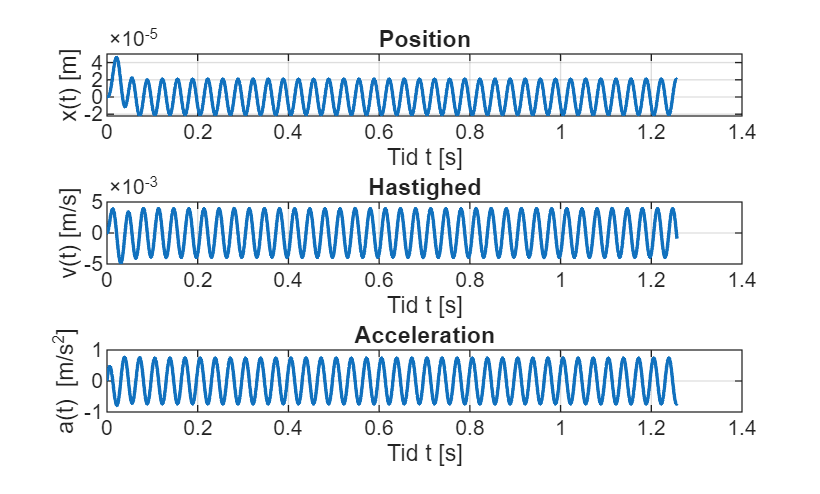


% Scenarie 2: "svage rystelser"

% Scenarie 2: "svag rystelse" (sinus-forstyrrelse)

m = 0.4;
k = 2000;
c = 40;           % din rolige løsning

x0 = 0;
v0 = 0;

F0 = 0.3;         % N (svag forstyrrelse)
f  = 30;          % Hz
F_func = @(t) F0*sin(2*pi*f*t);

opts.doPlot = true;
opts.verbose = true;

out2 = vibration_analysis_system(m,k,c,x0,v0,F_func,[],opts);